# ergoCub Fingers PID tuning

Copyright (C) 2023 Fondazione Istitito Italiano di Tecnologia (IIT)

All Rights Reserved.

## System identification and modelling 

### Read and plot datasets

#### Training Set

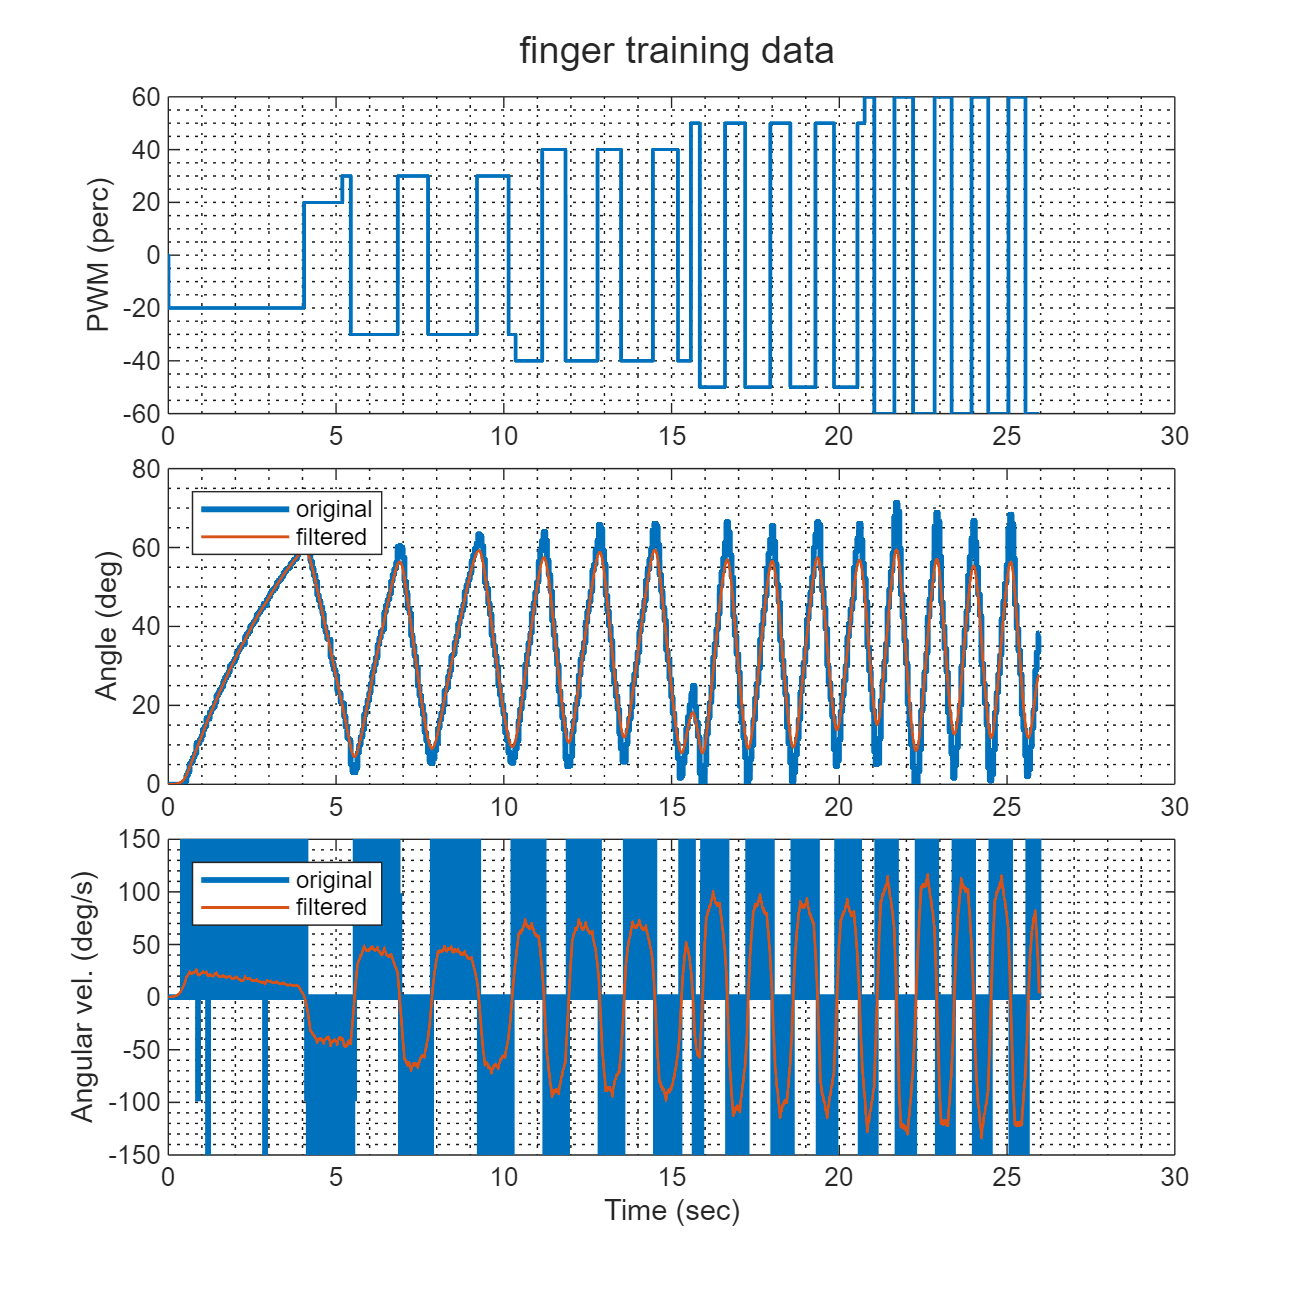

current_path = path();
addpath("scripts\");

if(~exist('fname', 'var') ||  ~exist('fpath', 'var'))
    [fname, fpath] = uigetfile('*');
end
[nameFile] = fileparts(fname);

filter_constant = 100;

downsample = false;

[training_table, Ts] = Reshape_dataset(fullfile(fpath,fname), filter_constant, downsample, 0, 3);

training_data = iddata(training_table.vel, training_table.pwm, Ts);
training_data.Name = "training";

f_train = figure('color', 'white','Position',[10 10 590 590]);
tiledlayout(3,1, "TileSpacing", "tight")

h1 = nexttile;
plot(training_table.Time, training_table.pwm);
ylabel("PWM (perc)")
h2 = nexttile;
plot(training_table.Time, training_table.pos_uf,'LineWidth',2);
hold on
plot(training_table.Time, training_table.pos,'LineWidth',1);
ylabel("Angle (deg)")
legend({"original", "filtered"},'Location','northwest')
h3 = nexttile;
plot(training_table.Time, training_table.vel_uf ,'LineWidth',2);
hold on
plot(training_table.Time, training_table.vel,'LineWidth',1);


legend({"original", "filtered"},'Location','northwest')
ylabel("Angular vel. (deg/s)")
ylim([-1 1]*150)
xlabel("Time (sec)")

linkaxes([h1 h2 h3], 'x')
sgtitle(strcat(nameFile, " finger training data"), Interpreter='none');

#### Validation Set

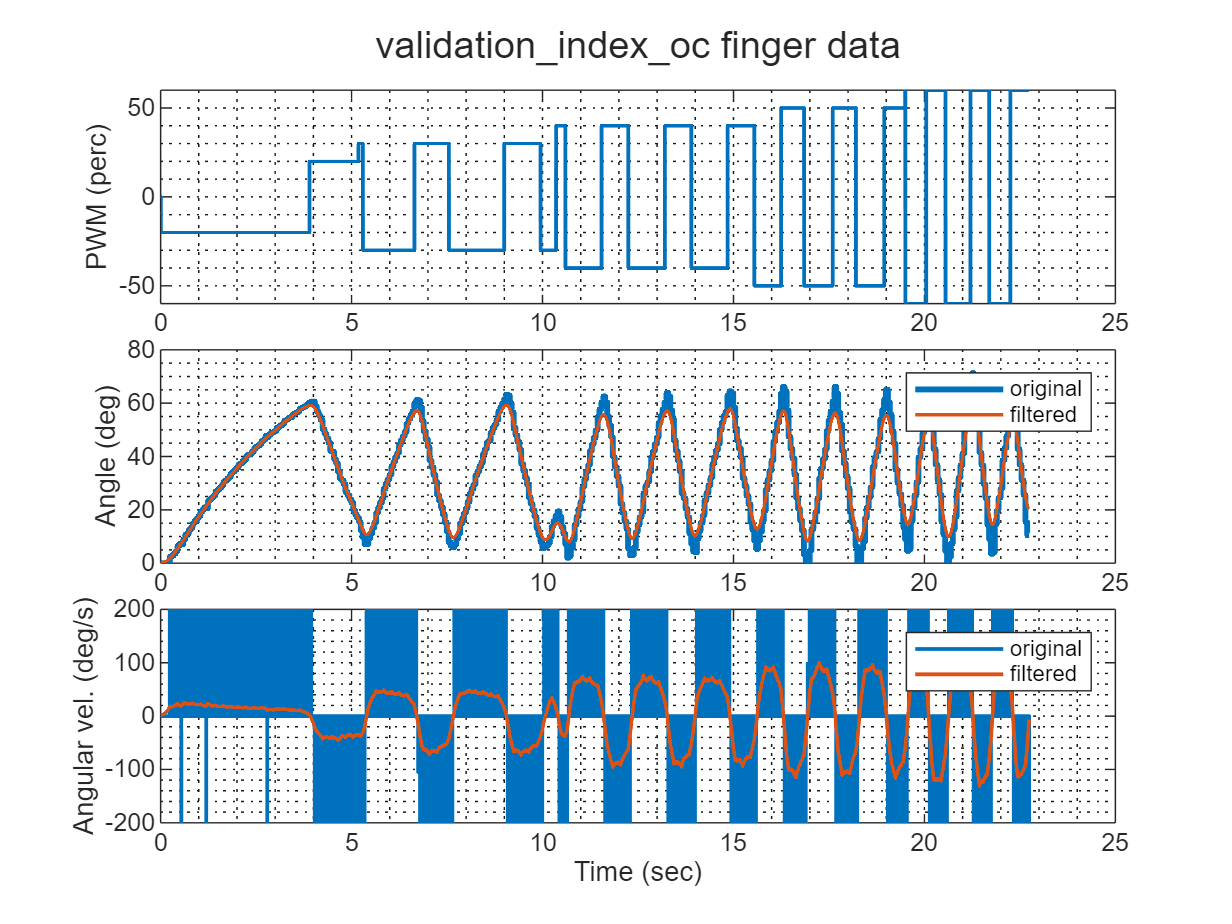

if(~exist('valid_name', 'var') ||  ~exist('valid_path', 'var'))
    [valid_name, valid_path] = uigetfile('*');
end
[pathstr, nameFile, ext] = fileparts(valid_name);

filter_constant = 100;

downsample = false;

[validation_table, Ts] = Reshape_dataset(fullfile(valid_path, valid_name), filter_constant, downsample, 0, 3);

validation_data = iddata(validation_table.vel, validation_table.pwm, Ts);
validation_data.Name = "validation";

figure('color', 'white');
tiledlayout(3,1, "TileSpacing", "tight")

h1 = nexttile;
plot(validation_table.Time, validation_table.pwm);
ylabel("PWM (perc)")
h2 = nexttile;
plot(validation_table.Time, validation_table.pos_uf,'LineWidth',2);
hold on
plot(validation_table.Time, validation_table.pos,'LineWidth',1.2);
ylabel("Angle (deg)")
legend({"original", "filtered"})
h3 = nexttile;
plot(validation_table.Time, validation_table.vel_uf);
hold on
plot(validation_table.Time, validation_table.vel);

legend({"original", "filtered"})
ylabel("Angular vel. (deg/s)")
ylim([-1 1]*200)
xlabel("Time (sec)")

linkaxes([h1 h2 h3], 'x')
sgtitle(nameFile + " finger data", interpreter="none")

### Run identification as process model

We target a continuous LTI model in the form


$$G(s) = \frac{k (s - z_1)}{(s - p_1) ( s - p_2)}$$


The poles can be real or complex conjugate. 

opt = procestOptions;
opt.InitialCondition =  "zero";
model = procest(training_data, "P2ZU", opt);

s = tf('s');
finger_tf = tf(model);
zpk(finger_tf)


ans =
 
  From input "u1" to output "y1":
  -17.163 (s+0.09302)
  --------------------
  (s+9.121) (s+0.7248)
 
Continuous-time zero/pole/gain model.
Model Properties


#### Plot results

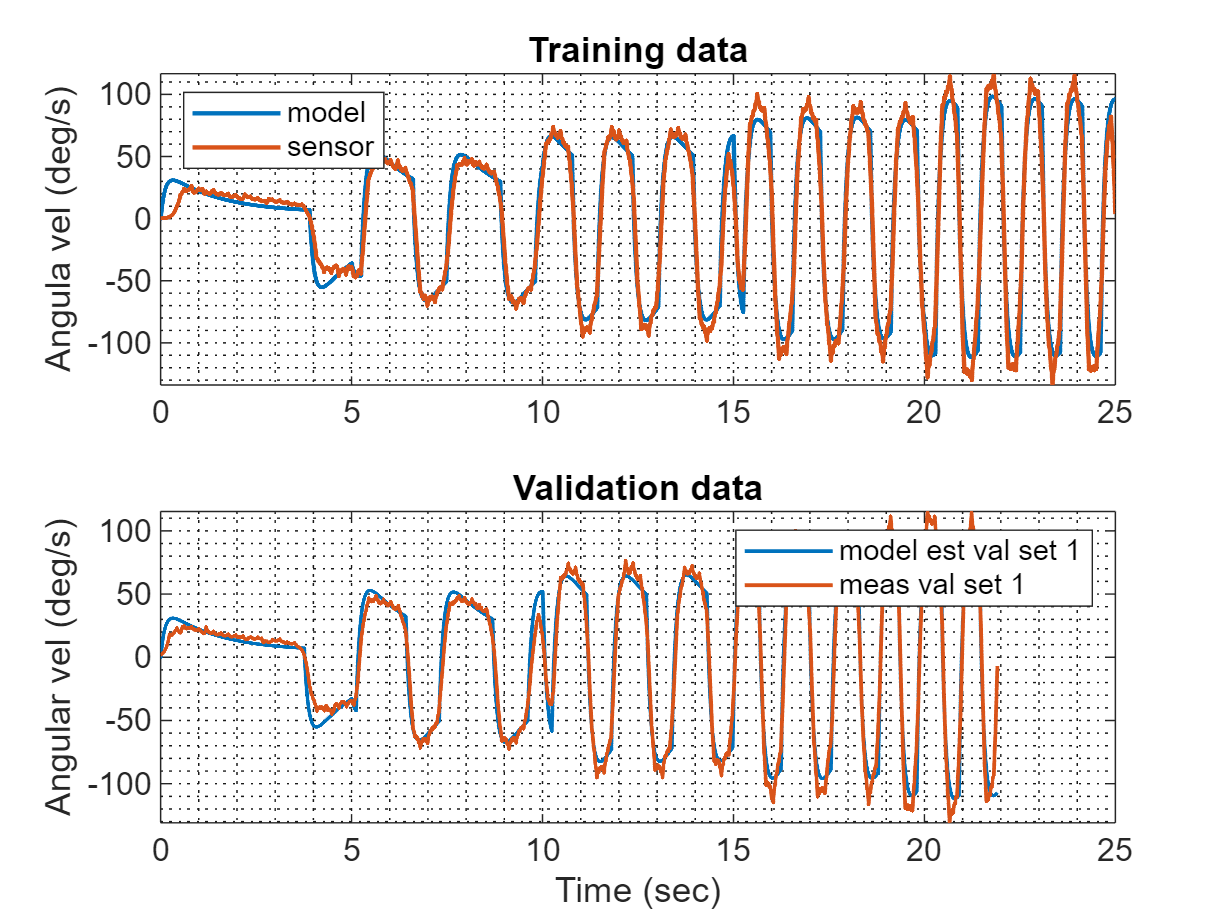

[rmse, fig_handle] = plot_results(finger_tf, training_data, validation_data, Ts, Ts);

disp(rmse)

     name: "Validation set 1 result"
    value: 10.554865150514



#### Add uncertainty

add_uncertainty = true;

finger_zpk = zpk(finger_tf);
poles = finger_zpk.P{1};
zeros = finger_zpk.Z{1};
k = finger_zpk.K;
tfu = k;

perc_uncertainty = 20;

if(add_uncertainty && isreal(poles))
    disp("Adding " + string(perc_uncertainty) + "% uncertainty to Poles");
    for i=1:length(poles)
        upole = ureal("p" + string(i), poles(i), "Percentage", [-perc_uncertainty, perc_uncertainty]);
        tfu = tfu / (s - upole);
    end
else
    for i=1:length(poles)
        tfu = tfu / (s - poles(i));
    end
end

Adding 20% uncertainty to Poles


if(add_uncertainty && isreal(zeros))
    disp("Adding " + string(perc_uncertainty) + "% uncertainty to Zeros");
    for i=1:length(zeros)
        uzero = ureal("z" + string(i), zeros(i), "Percentage", [-perc_uncertainty, perc_uncertainty]);
        tfu = tfu * (s - uzero);
    end
else
    for i=1:length(zeros)
        tfu = tfu * (s - zeros(i));
    end
end

Adding 20% uncertainty to Zeros



zpk(tfu)


ans =
 
  -17.163 (s+0.09302)
  --------------------
  (s+9.121) (s+0.7248)
 
Continuous-time zero/pole/gain model.
Model Properties


### Add integrator for position control

We change the IO relationship from  $\frac{\dot{\theta} }{u}$ to $\frac{\theta }{u}$  since we want to control the finger position.

tfu = tfu / s;

## Run autotuning

Here we define the specifications to tune the position controller in a robust way, and run the tuning algorithm.

#### Define tuning goals

Define the desired specifications.

select = 3;

switch select

    case (1)
        parSet = '001';
        disp('option 1 - SN 001')
        Ts_controller = 1e-3;   % sec
        responsetime = 0.25;     % sec
        dcerror = 0.001;        % perc
        peakerror = 1.02;       % fract relative
        maxOvershoot = 2;       % perc
        phase_margin = 80;      % deg
        gain_margin = 3;        % dB
    case (2) % for now equal to SN 001
        disp('option 2 - SN 002')
        parSet = '002';
        Ts_controller = 1e-3;   % sec
        responsetime = 0.4;     % sec
        dcerror = 0.001;        % perc
        peakerror = 1.00;       % fract relative
        maxOvershoot = 0;       % perc
        phase_margin = 80;      % deg
        gain_margin = 3;        % dB
    case (3) %choose this one to play with parameters
        disp('option 3 - custom')
        parSet = 'cus';
        Ts_controller = Ts;   % sec
        responsetime = 0.1;     % sec
        dcerror = 0.0001;        % perc
        peakerror = 1.02;       % fract relative
        maxOvershoot = 2;       % perc
        phase_margin = 80;      % deg
        gain_margin = 3;        % dB
end

option 3 - custom


par_summ = strcat('Ts controller: ', num2str(Ts_controller), ...
    ', responsetime: ', num2str(responsetime), ...
    ', dcerror: ', num2str(dcerror), ...
    ', peakerror: ', num2str(peakerror), ...
    ', Overshoot: ', num2str(maxOvershoot) );
disp(par_summ);

Ts controller:0.001, responsetime:0.1, dcerror:0.0001, peakerror:1.02, Overshoot:2


#### Define the goals.

tfu.InputName = "u";
tfu.OutputName = "y";

Rtrack = TuningGoal.Tracking('r', 'y', responsetime, dcerror, peakerror);
Rov = TuningGoal.Overshoot('r', 'y', maxOvershoot);
Rmargin = TuningGoal.Margins('y', gain_margin, phase_margin);

hard_goals = Rtrack;
soft_goals = [Rmargin, Rov];

disp('hard_goals: tracking ');

hard_goals: tracking 


disp('soft_goals: margin, overshoot');

soft_goals: margin, overshoot


#### Tune up the controller

pid_type = 'PID';

[C, T] = design_robust_pid(tfu, soft_goals, hard_goals, pid_type);

Nominal tuning:
Design 1: Soft = 1.26, Hard = 1.1598
Design 2: Soft = 1.28, Hard = 1.1598
Design 3: Soft = 1.19, Hard = 1.1599
Design 4: Soft = 1.24, Hard = 1.1598
Design 5: Soft = 1.19, Hard = 1.1599
Design 6: Soft = 1.34, Hard = 1.1599
Design 7: Soft = 1.3, Hard = 1.1599
Design 8: Soft = 1.25, Hard = 1.1598
Design 9: Soft = 1.18, Hard = 1.16
Design 10: Soft = 1.26, Hard = 1.1598
Design 11: Soft = 1.25, Hard = 1.1598

Robust tuning of Design 4:
Soft: [1.24,Inf], Hard: [1.16,1.43], Iterations = 34
Soft: [1.38,Inf], Hard: [1.17,1.19], Iterations = 25
Soft: [1.55,Inf], Hard: [1.19,1.19], Iterations = 20
Soft: [1.56,Inf], Hard: [1.19,1.19], Iterations = 20
Final: Soft = 1.56, Hard = 1.1866, Iterations = 99

Robust tuning of Design 11:
Soft: [1.25,Inf], Hard: [1.16,1.43], Iterations = 38
Soft: [1.42,Inf], Hard: [1.17,1.19], Iterations = 26
Soft: [1.56,Inf], Hard: [1.19,1.19], Iterations = 20
Soft: [1.56,Inf], Hard: [1.19,1.19], Iterations = 20
Final: Soft = 1.56, Hard = 1.1866, Iterations 

#### Plot tuning results

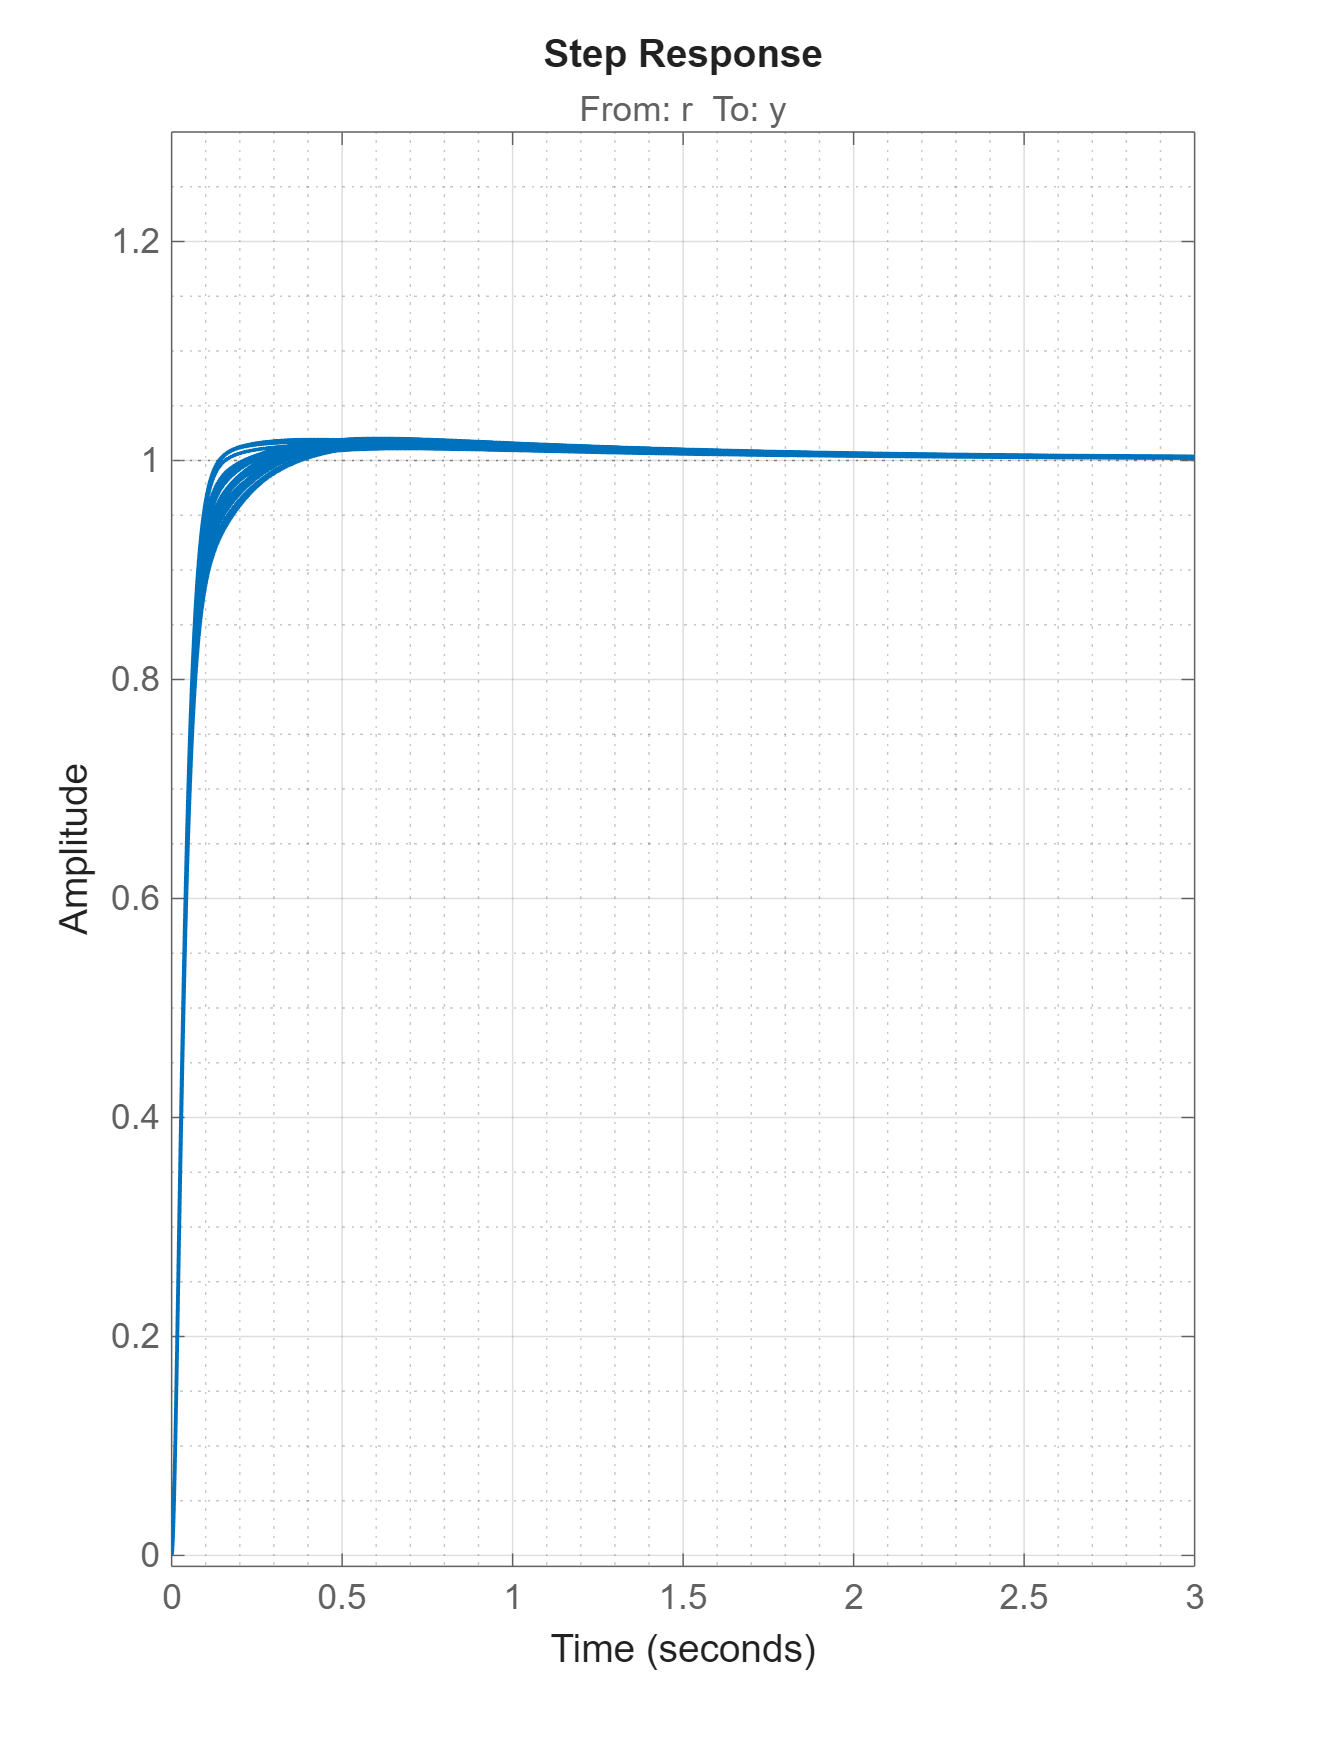

f_step = figure('color', 'white','Position',[10 10 900 1200]);
step(T, 3);
ylim([-0.01, 1.3])
grid('minor');

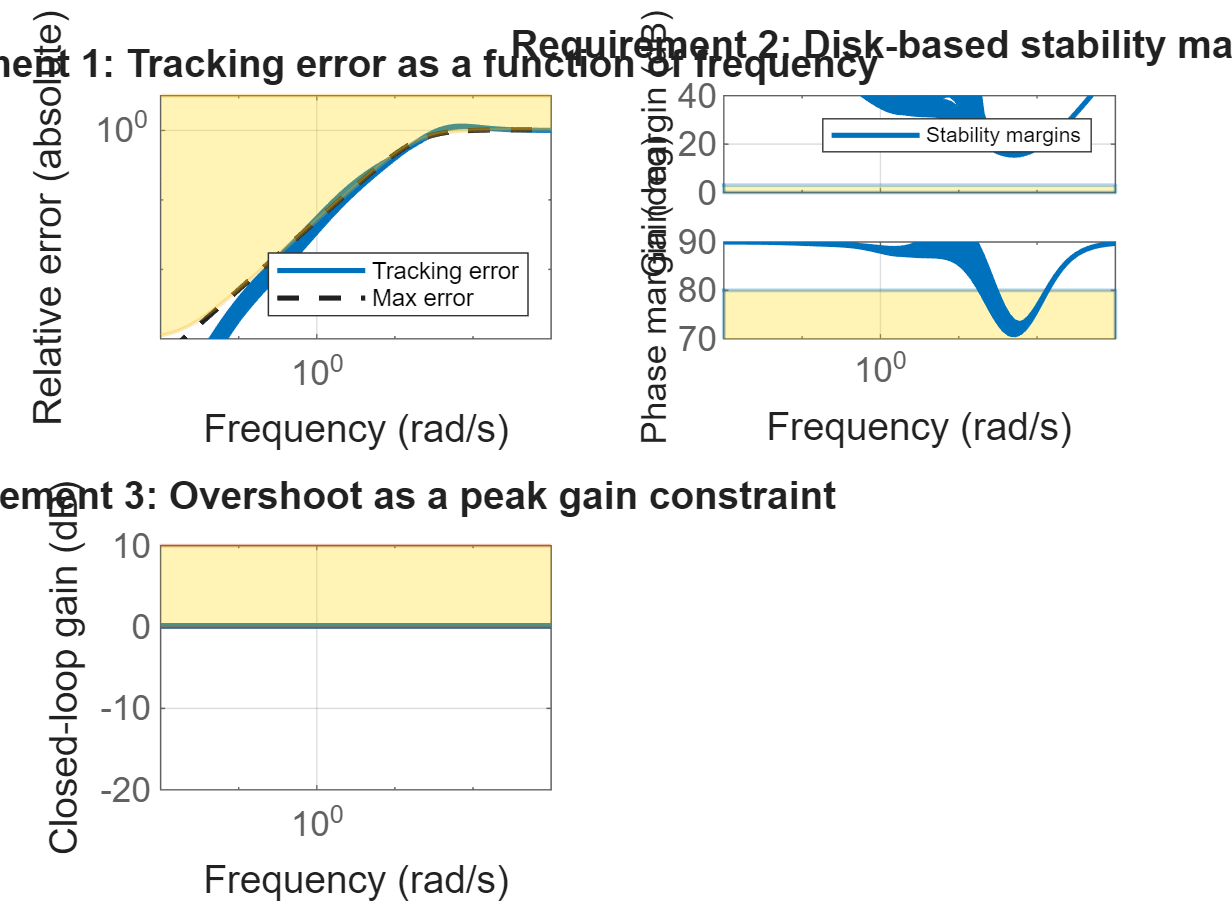

f_plots = figure('color', 'white');

viewGoal([hard_goals soft_goals], T)

Get the discretized controller.

Cz = c2d(C, Ts_controller, 'tustin')


Cz =
 
            Ts*(z+1)                 1         
  Kp + Ki * -------- + Kd * -------------------
            2*(z-1)         Tf+Ts/2*(z+1)/(z-1)

  with Kp = -11.3, Ki = -11.7, Kd = -1.34, Tf = 0.01, Ts = 0.001
 
Sample time: 0.001 seconds
Discrete-time PIDF controller in parallel form.
Model Properties


table(["Proportional", "Integral", "Derivative"]', [Cz.Kp Cz.Ki Cz.Kd]', VariableNames = ["Param", "Value"])

ans = 3×2 table
        Param               Value      
    ______________    _________________

    "Proportional"    -11.3271318456723
    "Integral"        -11.7287705870396
    "Derivative"      -1.33604078813836


% saveas(f_train, f_name);
% exportgraphics(f_train, f_name);
% exportgraphics(f_resume, f_name,'append',true);
% exportgraphics(f_plots, f_name,'append',true);
kappapi = Cz.Kp;
kappai = Cz.Ki;
kappadi = Cz.Kd;

path(current_path);

%to save the kp, ki and kd coefficents uncomment the following line
%save(strcat('results/', nameFile,'-',parSet,'_',tYpe,'.mat'), 'nameFile','kappapi', 'kappai','kappadi')
% writematrix([nameFile , num2str(kappapi) , num2str(kappai) , num2str(kappadi)],strcat('results/', nameFile,'-',parSet,'_',tYpe,'.csv'))

% to obtain a pdf report uncomment the following  line 
% export('identification_tuning_v2.mlx',strcat('results/',nameFile,'-',parSet,'_',tYpe,'.pdf'), Format = "pdf", HideCode = true);